# The Nystrom Low-Rank Approximation

The Nystrom approximation in machine learning is a method for computing a low-rank approximation to a symmetric, positive definite kernel matrix. To explain this approximation, we first explain the Nystrom method for numerically solving an integral operator eigenproblem. The Nystrom low-rank approximation will be easy to explain after that.

#### Integral operator eigenproblem and its numerical solution

Consider the integral operator eigenproblem


$$\int \kappa(x,y) \, \phi(y) \, dy = \lambda \, \phi(x)$$


with kernel function $\kappa(x,y)$. Like for the matrix eigenproblem, there are multiple solutions. Let $\lambda_k$ denote an eigenvalue and let $\phi_k(x)$ denote the corresponding eigenfunction. Approximating the integral by quadrature over the set of points $x_1, \ldots, x_m$ leads to the matrix eigenproblem


$$K_{mm} u^{(m)} = \lambda^{(m)} u^{(m)}$$


where $K_{mm}$ is an $m \times m$ kernel matrix. The $k$-th eigenvalue of the integral operator is approximated by


$$\lambda_k \approx \lambda_k^{(m)} / m$$


where $\lambda_k^{(m)}$ is the $k$-th matrix eigenvalue. The eigenfunction evaluated at a point $x$ is approximated by


$$\phi_k(x) \approx \frac{\sqrt{m}}{\lambda_k^{(m)}} \sum_{j=1}^m \kappa(x,x_j) [u_k^{(m)}]_j$$


where $[u_k^{(m)}]_j$ is the $j$-th component of the $k$-th eigenvector of $K_{mm}$.

As an example, will consider an integral operator eigenproblem with a Gaussian kernel function and plot numerical solutions utilizing different numbers $m$ of quadrature points.

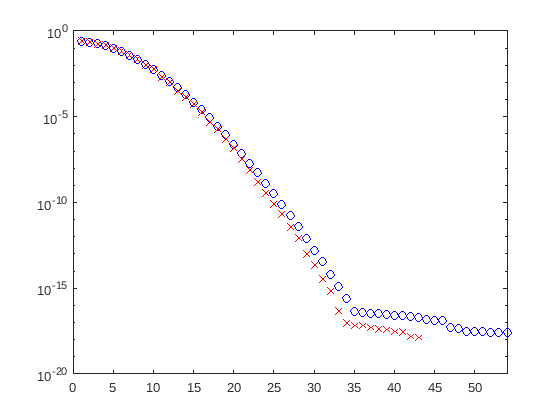

m = 54;
lenscale = 0.1;
xm = sort(rand(m,1));
Kmm = exp(-0.5*((xm-xm')/lenscale).^2);
[Um, Dm] = eig(Kmm, 'vector');
[Dm, ind] = sort(Dm, 'descend');
Um = Um(:,ind);

% compare to solution using a large number of quadrature points
xn = (0.0005:0.001:1)';
n = length(xn);
Knn = exp(-0.5*((xn-xn')/lenscale).^2);
[Un, Dn] = eig(Knn, 'vector');
[Dn, ind] = sort(Dn, 'descend');
Un = Un(:,ind);

% plot the eigenvalues of integral operator
figure
warning('off','MATLAB:Axes:NegativeDataInLogAxis')
semilogy(1:n, Dn/n, 'bo', 1:m, Dm/m, 'rx');
xlim([0 m]);

There are 9 eigenvalues above $10^{-15}$. In the plot, we observe that these eigenvalues are fairly well approximated.

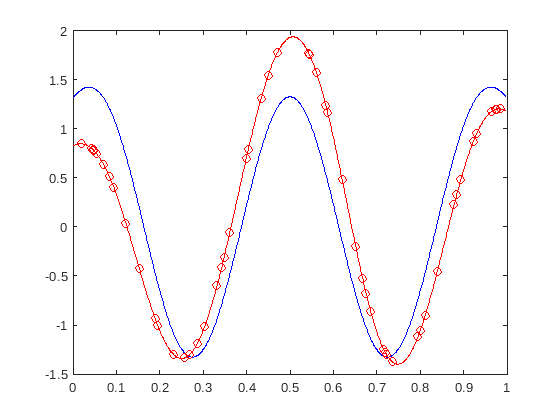

% Plot k-th eigenfunction (blue) and its approximation (red)
k = 5;
if Dm(k) < 1e-12, warning('very small corresponding eigenvalue'), end
figure
plot(xn, sqrt(n)*Un(:,k)*sign(Un(1,k)), 'b') % use sign to try match sign of Un and Um
hold on
plot(xm, sqrt(m)*Um(:,k)*sign(Um(1,k)), 'ro')

% Nystrom extension from m points to n points for k-th eigenfunction
Knm = exp(-0.5*((xn-xm')/lenscale).^2);
ext = sqrt(m)/Dm(k) * (Knm*Um(:,k));
plot(xn, ext*sign(Um(1,k)), 'r-')

#### Nystrom low-rank approximation and approximation of eigenvectors

The Nystrom approximations to the $k$-th eigenvalue and eigenvector of $K_{nn}$ are, respectively,


$$\tilde{\lambda}_k^{(n)} = \frac{n}{m} \lambda_k^{(m)}$$



$$\tilde{u}_k^{(n)} = \sqrt{\frac{m}{n}} \frac{1}{\lambda_k^{(m)}} K_{nm} u_k^{(m)}$$


These approximations are used to compute the low-rank approximation


$$K_{nn} \approx \sum_{k=1}^{m} \tilde{\lambda}_k^{(n)} \tilde{u}_k^{(n)} (\tilde{u}_k^{(n)})^T$$


Continuing the above example, we will compute a low-rank approximation to $K_{nn}$. First compute the matrix of approximate eigenvalues and the matrix of the first $m$ approximate eigenvectors.

D = (n/m)*diag(Dm);
U = sqrt(m/n)*(Knm*Um*(diag(1./Dm)));

The relative error of the low-rank approximation is

relerr = norm(Knn-U*D*U', 'fro')/norm(Knn, 'fro')

relerr = 1.6352e-09

Let's check the norm and orthogonality of some of the eigenvectors.

norm(U(:,1))

ans = 1.0104

norm(U(:,2))

ans = 0.9812

U(:,1)'*U(:,2)

ans = -0.0129

These approximations are generally not normalized nor mutually orthogonal.

#### Exercises

- What happens to the quality of the approximations when $m$ is smaller than the number of nonzero eigenvalues of the integral operator?

#### References

[1] Williams, C. K. I.; Seeger, M. (2001). "Using the Nyström method to speed up kernel machines". *Advances in Neural Information Processing Systems*, 13, Proceedings of the 2000 Conference, pp. 682–688.

[2] Nyström, Evert Johannes (1930). "Über die praktische Auflösung von Integralgleichungen mit Anwendungen auf Randwertaufgaben". *Acta Mathematica*, 54 (1): pp. 185–204.